close all; clc

% constants
m = 1500;
Kc = 110;
Kf = 2.5;
Ka = 1;
Ki = 15; % change to 150 for part d)
Kp = 500;
vd = 30;

% equilibrium point
eq = [1/Ki*(Kc+Kf*vd+Ka*vd^2), vd]

eq =    72.3333   30.0000



% type of equilibrium point
% syms x1 x2 Ki
% f1 = -x2 + vd
% f2 = 1/m*(Ki*x1 + Kp*(vd-x2) - Kc*sign(x2)- Kf*x2 - Ka*x2^2)
% J = jacobian([f1 f2], [x1 x2]);
% J = subs(J, [x1 x2], eq)
% eig(J)

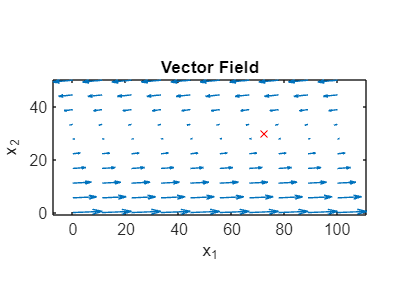

% Create vector field
x = linspace(0,100,10);
y = linspace(0,50,10);
[X,Y] = meshgrid(x,y);

u = Ki*X+Kp*(vd-Y); % part c) and part d)
u = min(1800, max(0, u)); % saturation for part e)

DX = -Y + vd;                 
DY = 1/m*(u-Kc*sign(Y)-Kf*Y-Ka*Y.^2);

% make arrows the same length
quiver(X,Y,DX,DY,1);
xlabel('x_1')
ylabel('x_2')
axis tight equal;
title("Vector Field")

hold on;
plot(eq(1), eq(2), 'rx')
hold off;